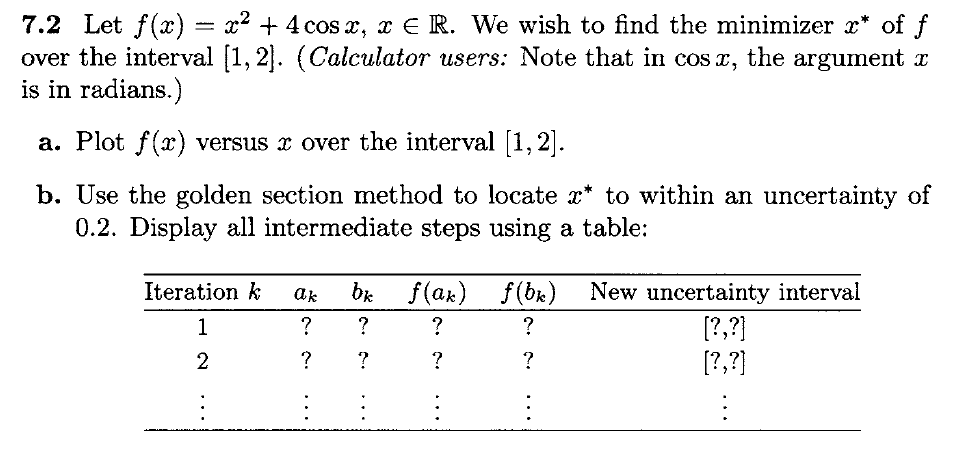

a)

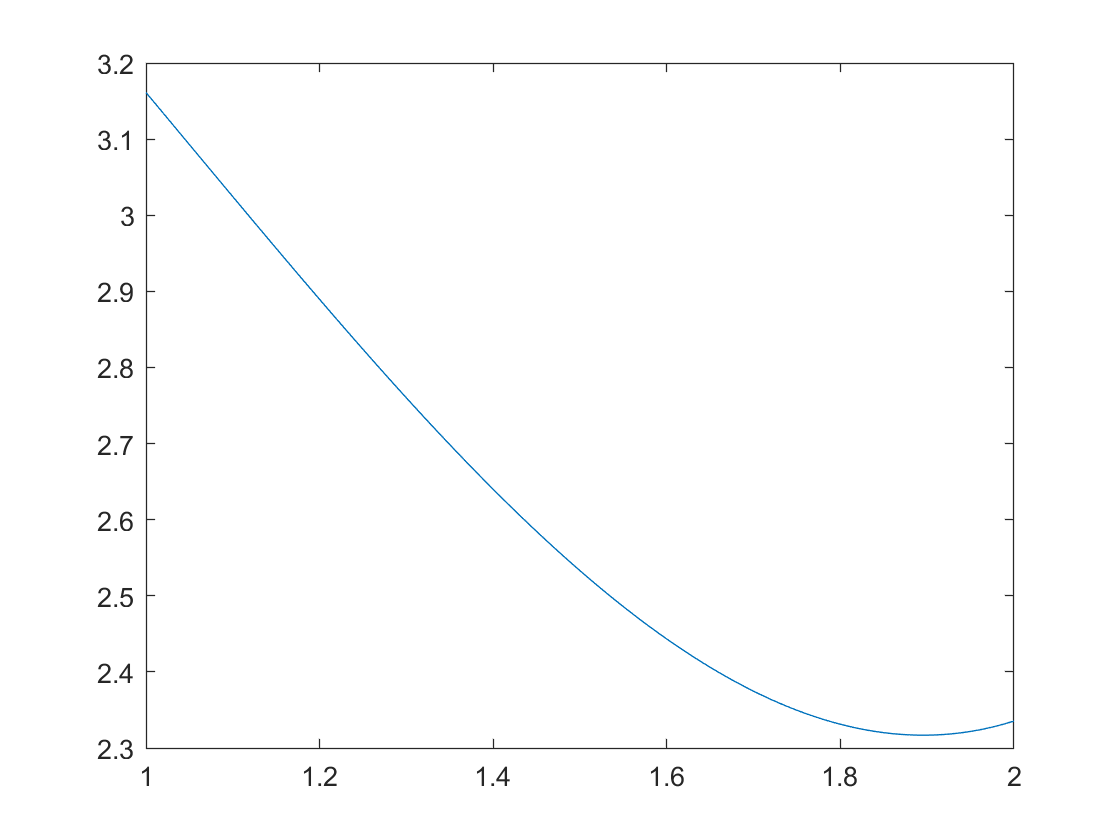

x = 1:.01:2;
f_x = x.^2+4*cos(x);
plot(x,f_x)

b) 

p = (3-sqrt(5))/2

p = 0.3820

% (1-p)^N <= 0.2/2-1

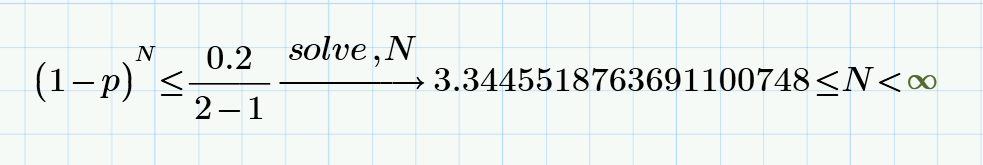

So we need more than 3.34 steps, eg 4 steps

clear
clc
p = (3-sqrt(5))/2;
% (1-p)^N <= 0.2/2-1
a0 = 1;
b0 = 2;

a_k = a0;
b_k = b0;
a_k_old = a_k;
b_k_old = b_k;
firstrun = 1;
for k=1:4
    if(firstrun == 1)
        a_k = a_k_old+p*(b_k_old-a_k_old);
        b_k = a_k_old+(1-p)*(b_k_old-a_k_old);
        f_x_ak = a_k.^2+4*cos(a_k);
        f_x_bk = b_k.^2+4*cos(b_k);
    else
        if(f_x_ak > f_x_bk)
        a_k_new = b_k;
        b_k_new = a_k_old+(1-p)*(b_k_old-a_k_old);
        else
        b_k_new = a_k;
        a_k_new = a_k_old+p*(b_k_old-a_k_old);
        end
        f_x_ak = a_k_new.^2+4*cos(a_k_new);
        f_x_bk = b_k_new.^2+4*cos(b_k_new);
        a_k = a_k_new;
        b_k = b_k_new;
    end
    if(f_x_ak > f_x_bk)
        interval = [a_k b_k_old];
        a_k_old = a_k;
    else
        interval = [a_k_old b_k];
        b_k_old = b_k;
    end
    firstrun = 0;
    iter(k,:) = [k a_k b_k f_x_ak f_x_bk interval]
end

iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000


iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000
    2.0000    1.6180    1.7639    2.4292    2.3437    1.6180    2.0000


iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000
    2.0000    1.6180    1.7639    2.4292    2.3437    1.6180    2.0000
    3.0000    1.7639    1.8541    2.3437    2.3196    1.7639    2.0000


iter =     1.0000    1.3820    1.6180    2.6607    2.4292    1.3820    2.0000
    2.0000    1.6180    1.7639    2.4292    2.3437    1.6180    2.0000
    3.0000    1.7639    1.8541    2.3437    2.3196    1.7639    2.0000
    4.0000    1.8541    1.9098    2.3196    2.3171    1.8541    2.0000


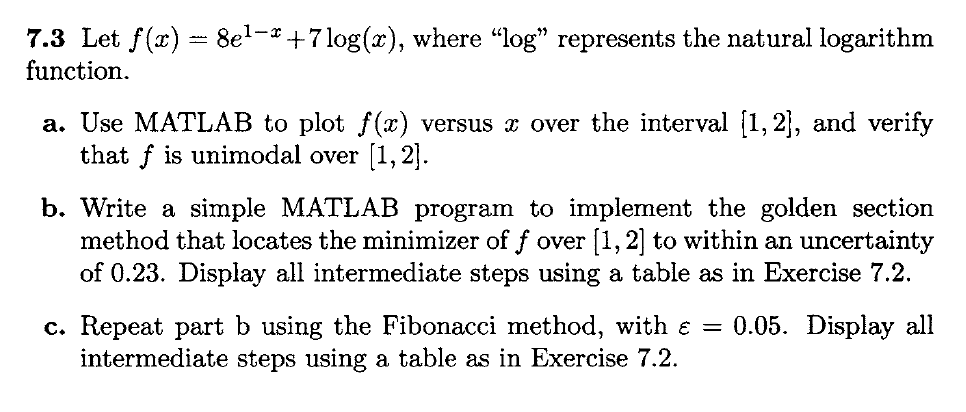

a)

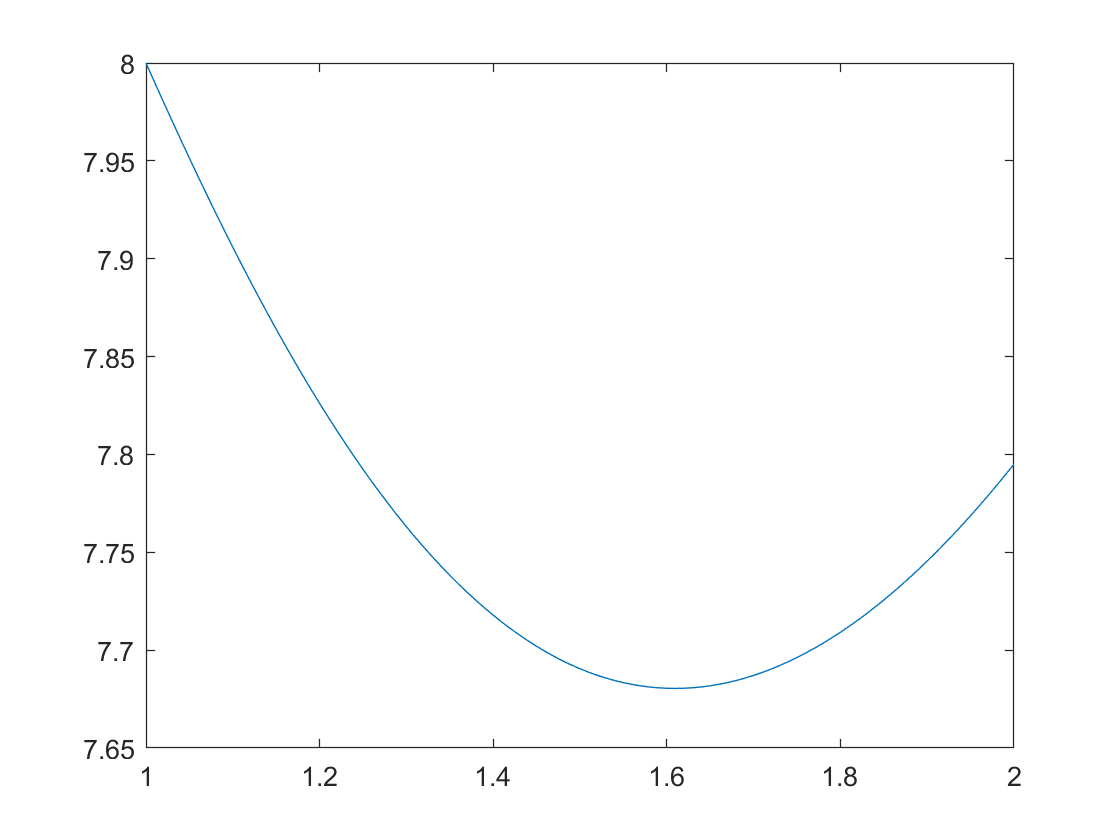

clear, clc;
x = 1:.01:2;
f_x = 8*exp(1-x)+7*log(x);
plot(x,f_x)

b)

clear
clc
p = (3-sqrt(5))/2;
% (1-p)^N <= 0.2/2-1
a0 = 1;
b0 = 2;

a_k = a0;
b_k = b0;
a_k_old = a_k;
b_k_old = b_k;
firstrun = 1;
for k=1:4
    if(firstrun == 1)
        a_k = a_k_old+p*(b_k_old-a_k_old);
        b_k = a_k_old+(1-p)*(b_k_old-a_k_old);
        f_x_ak = 8*exp(1-a_k)+7*log(a_k);
        f_x_bk = 8*exp(1-b_k)+7*log(b_k);
    else
        if(f_x_ak > f_x_bk)
        a_k_new = b_k;
        b_k_new = a_k_old+(1-p)*(b_k_old-a_k_old);
        else
        b_k_new = a_k;
        a_k_new = a_k_old+p*(b_k_old-a_k_old);
        end
        f_x_ak = 8*exp(1-a_k_new)+7*log(a_k_new);
        f_x_bk = 8*exp(1-b_k_new)+7*log(b_k_new);
        a_k = a_k_new;
        b_k = b_k_new;
    end
    if(f_x_ak > f_x_bk)
        interval = [a_k b_k_old];
        a_k_old = a_k;
    else
        interval = [a_k_old b_k];
        b_k_old = b_k;
    end
    firstrun = 0;
    iter(k,:) = [k a_k b_k f_x_ak f_x_bk interval]
end

iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000


iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    2.0000    1.6180    1.7639    7.6805    7.6995    1.3820    1.7639


iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    2.0000    1.6180    1.7639    7.6805    7.6995    1.3820    1.7639
    3.0000    1.5279    1.6180    7.6860    7.6805    1.5279    1.7639


iter =     1.0000    1.3820    1.6180    7.7247    7.6805    1.3820    2.0000
    2.0000    1.6180    1.7639    7.6805    7.6995    1.3820    1.7639
    3.0000    1.5279    1.6180    7.6860    7.6805    1.5279    1.7639
    4.0000    1.6180    1.6738    7.6805    7.6838    1.5279    1.6738


c) Fibonacci method

F = @myF;

left = 1;
right = 2;
uncert = 0.23;
epsilon = 0.05;

N = 0;






function y = myF(x)
    y = 8*exp(1-x)+7*log(x);
end
